## Credits

Created: Martha N. Acosta, 18.01.2021

Supervised: Professor Francisco M. Gonzalez-Longatt

Github: [https://github.com/fglongatt/PowerSystemOperation](https://github.com/fglongatt/PowerSystemOperation)

### References:

     [1] Ebrahim Vaaheli, Practical Power System Operation. Hoboken, New Jersey: John Wiley & Sons, Inc., 2014.

     [2] Hadi Saadat, Power System Analysis. New York:  McGraw-Hill Companies, 1999. 

# **Least Square Method for State Estimation**

Least square is a mathematical method to obtain the state variable values by minimizing the estimation error. The mathematical formulation can be stated as [1]: 

$\min \;J\left(\mathbf{x}\right)=\sum_{i=1}^n \frac{{\left(Z_i -f_i \left(\mathbf{x}\right)\right)}^2 }{\sigma_i }$               (1)

where : 

$\mathbf{x}:$ is the state vector. 

$Z_i$ : represent the value of the *i*-th measurement. The measurements can be a voltage (V), active power (P), reactive power (Q)

$f_i \left(\mathbf{x}\right)$: represent the *i*-th function to estimate the state variables being measured by the *i*-th measurement. 

$\sigma_i$ : is the covariance of the  *i*-th measurement.

*n: *is the total number of measurements*.*

Equation (1) can be written in matrix form  as: 

$\min \;\mathbf{J}\left(\mathbf{x}\right)={\left\lbrack \mathbf{Z}-\mathbf{F}\left(\mathbf{x}\right)\right\rbrack }^{\mathrm{T}} {\mathbf{R}}^{-1} \left\lbrack \mathbf{Z}-\mathbf{F}\left(\mathbf{x}\right)\right\rbrack$              (2)

where: 

                                        
$$\mathbf{Z}=\left\lbrack \begin{array}{c}
Z_{\mathrm{1}} \\
Z_2 \\
\vdots \\
Z_i \\
\vdots \\
Z_n 
\end{array}\right\rbrack$$
      
$$\mathbf{F}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{c}
f_{\mathrm{1}} \left(\mathbf{x}\right)\\
f_{\mathrm{1}} \left(\mathbf{x}\right)\\
\vdots \\
f_i \left(\mathbf{x}\right)\\
\vdots \\
f_n \left(\mathbf{x}\right)
\end{array}\right\rbrack$$
     
$$\mathbf{R}=\left\lbrack \begin{array}{cccccc}
\sigma_1^2  & 0 & 0 & 0 & 0 & 0\\
0 & \sigma_2^2  & 0 & 0 & 0 & 0\\
0 & 0 & \ddots  & 0 & 0 & 0\\
0 & 0 & 0 & \sigma_i^2  & 0 & 0\\
0 & 0 & 0 & 0 & \ddots  & 0\\
0 & 0 & 0 & 0 & 0 & \sigma_n^2 
\end{array}\right\rbrack$$


The minimum of **J **is obtained by solving  the unconstrained minimization problem of $\frac{\partial }{\partial x}\mathbf{J}=\frac{\partial }{\partial x}\left({\left\lbrack \mathbf{Z}-\mathbf{F}\left(\mathbf{x}\right)\right\rbrack }^{\mathrm{T}} {\mathbf{R}}^{-1} \left\lbrack \mathbf{Z}-\mathbf{F}\left(\mathbf{x}\right)\right\rbrack \right)=0$ and the results is: 

      ${\mathbf{H}}^{\mathrm{T}} \left(\mathbf{x}\right){\mathbf{R}}^{-1} \left(\mathbf{Z}-\mathbf{F}\left(\mathbf{x}\right)\right)=0$                 (3)

where **H**(**x**) is the derivative of **F**(**x**) or the Jacobian of **F**(**x**):


$$\mathbf{H}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{cccccc}
\frac{{\partial f}_{\mathrm{1}} \left(\mathbf{x}\right)}{{\partial x}_1 } & \frac{{\partial f}_{\mathrm{1}} \left(\mathbf{x}\right)}{{\partial x}_2 } & \cdots  & \frac{{\partial f}_{\mathrm{1}} \left(\mathbf{x}\right)}{{\partial x}_j } & \cdots  & \frac{{\partial f}_{\mathrm{1}} \left(\mathbf{x}\right)}{{\partial x}_m }\\
\frac{{\partial f}_2 \left(\mathbf{x}\right)}{{\partial x}_1 } & \frac{{\partial f}_2 \left(\mathbf{x}\right)}{{\partial x}_2 } & \cdots  & \frac{{\partial f}_2 \left(\mathbf{x}\right)}{{\partial x}_j } & \cdots  & \frac{{\partial f}_2 \left(\mathbf{x}\right)}{{\partial x}_m }\\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
\frac{{\partial f}_i \left(\mathbf{x}\right)}{{\partial x}_1 } & \frac{{\partial f}_i \left(\mathbf{x}\right)}{{\partial x}_2 } & \cdots  & \frac{{\partial f}_i \left(\mathbf{x}\right)}{{\partial x}_j } & \cdots  & \frac{{\partial f}_i \left(\mathbf{x}\right)}{{\partial x}_m }\\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
\frac{{\partial f}_n \left(\mathbf{x}\right)}{{\partial x}_1 } & \frac{{\partial f}_n \left(\mathbf{x}\right)}{{\partial x}_2 } & \cdots  & \frac{{\partial f}_n \left(\mathbf{x}\right)}{{\partial x}_j } & \cdots  & \frac{{\partial f}_n \left(\mathbf{x}\right)}{{\partial x}_m }
\end{array}\right\rbrack$$


where *m* is the number of state variables. To solve the nonlinear equation (3), the Newton–Raphson method, which deploys linearization, can be used. This way, the following equation should be solved iteratively:

${\mathbf{x}}_{k+1} ={\mathbf{x}}_k +{\left({\mathbf{H}}_k^{\mathrm{T}} {\mathbf{R}}^{-1} {\mathbf{H}}_k \right)}^{-1} {\mathbf{H}}_k^{\mathrm{T}} {\mathbf{R}}^{-1} \left(\mathbf{Z}-\mathbf{F}\left({\mathbf{x}}_k \right)\right)$            (4)

where *k*+1 represent the current iteration.  

For a linear system, $\mathbf{F}\left(\mathbf{x}\right)=\textrm{Hx}$ and  the equation (4) can be written as 

             $\mathbf{x}={\left({\mathbf{H}}_k^{\mathrm{T}} {\mathbf{R}}^{-1} {\mathbf{H}}_k \right)}^{-1} {\mathbf{H}}_k^{\mathrm{T}} {\mathbf{R}}^{-1} \mathbf{Z}$                              (5)

clear all
clc
close all

## EXAMPLES 

#### 2.3.3.2 Linear System Example 

Consider an example with the network configuration shown in Figure 1. The measurements vector, network equations and the covariances are: 

      
$$\mathbf{Z}=\left\lbrack \begin{array}{c}
Z_{\mathrm{1}} \\
Z_2 \\
Z_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
P_{\textrm{12}} \\
P_{13} \\
P_{32} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 6\\
0\ldotp 7\\
0\ldotp 4
\end{array}\right\rbrack$$
       
$$\begin{array}{l}
{\mathrm{M}}_{\textrm{12}} =f_{\mathrm{1}} \left(\Theta_1 ,\Theta_2 \right)=4\Theta_1 -4\Theta_2 \\
{\mathrm{M}}_{\textrm{13}} =f_2 \left(\Theta_1 ,\Theta_2 \right)=2\Theta_1 \\
{\mathrm{M}}_{\textrm{32}} =f_2 \left(\Theta_1 ,\Theta_2 \right)=-5\Theta_2 
\end{array}$$
        
$$\begin{array}{l}
\sigma_1^2 =3\times {10}^{-4} \\
\sigma_2^2 =2\times {10}^{-4} \\
\sigma_3^2 =1\times {10}^{-4} 
\end{array}$$


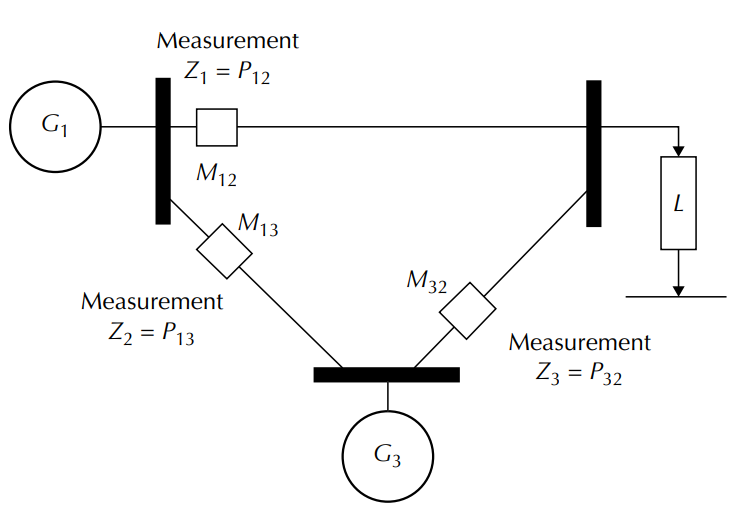

Figure 1.  State estimation results 

***Procedure: ***

- Define the state variables,  $\mathbf{x}=\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\Theta_1  & \Theta_2 
\end{array}\right\rbrack$. 

syms x1 x2   % Creating  simbolic variables
x = [x1;x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

         2. Creare the vector of mesurements ($\mathit{\mathbf{Z}}$) and  the vector of network equations ($\mathbf{F}\left(\mathbf{x}\right)$): 

Z = [0.6; 0.7;0.4]

Z =     0.6000
    0.7000
    0.4000


Fx =[4*x1-4*x2;2*x1;-5*x2]

$$Fx = \left(\begin{array}{c} 4\,x_{1}-4\,x_{2}\\ 2\,x_{1}\\ -5\,x_{2} \end{array}\right)$$

         3. Create the covarince matrix ($\mathbf{R}$):   

r=[3e-4;2e-4;1e-4];
R = diag(r)

R = 	1.0e+-3 *

    0.3000         0         0
         0    0.2000         0
         0         0    0.1000


         4. Compute the jacobian matrix  $\mathbf{H}\left(\mathbf{x}\right)$: 

m = 3; % number of network equations 
n = 2; % number of state variables

for i = 1:m
    for j = 1:n
        H(i,j)=diff(Fx(i),x(j));
    end
end
H

$$H = \left(\begin{array}{cc} 4 & -4\\ 2 & 0\\ 0 & -5 \end{array}\right)$$

       5. Compute the state variables using equation (5): 

xnew = double(inv(H'*inv(R)*H)*H'*inv(R)*Z)     

xnew =     0.1576
   -0.0646


       6. Solve the network equations ($\mathbf{F}\left(\mathbf{x}\right)$) : 

Fx = subs(Fx,x,xnew) 

$$Fx = \left(\begin{array}{c} \frac{431}{485}\\ \frac{917}{2910}\\ \frac{94}{291} \end{array}\right)$$

double(Fx )

ans =     0.8887
    0.3151
    0.3230



clearvars x R Z H 

#### 2.3.3.3 Nonlinear System Example 

To demonstrate a nonlinear case, the two bus system of Figure 2 is considered.

      
$$\mathbf{Z}=\left\lbrack \begin{array}{c}
Z_{\mathrm{1}} \\
Z_2 \\
Z_3 \\
Z_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
P_{12} \\
Q_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\ldotp 02\\
1\ldotp 0\\
2\ldotp 0\\
0\ldotp 2
\end{array}\right\rbrack$$
        
$$\begin{array}{l}
f_{\mathrm{1}} \left(\delta_2 ,V_1 ,V_2 \right)=V_1 \\
f_2 \left(\delta_2 ,V_1 ,V_2 \right)=V_2 \\
f_3 \left(\delta_2 ,V_1 ,V_2 \right)=-10V_1 V_2 \sin \delta_2 \\
f_4 \left(\delta_2 ,V_1 ,V_2 \right)=10V_1^2 -10V_1 V_2 \cos \delta_2 
\end{array}$$
          
$$\begin{array}{l}
\sigma_1 =0\ldotp 05\\
\sigma_2 =0\ldotp 05\\
\sigma_3 =0\ldotp 1\\
\sigma_4 =0\ldotp 1
\end{array}$$
           
$${\mathbf{x}}_0 =\left\lbrack \begin{array}{c}
\delta_2 \\
V_1 \\
V_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\ldotp 02\\
1\ldotp 0
\end{array}\right\rbrack$$
 

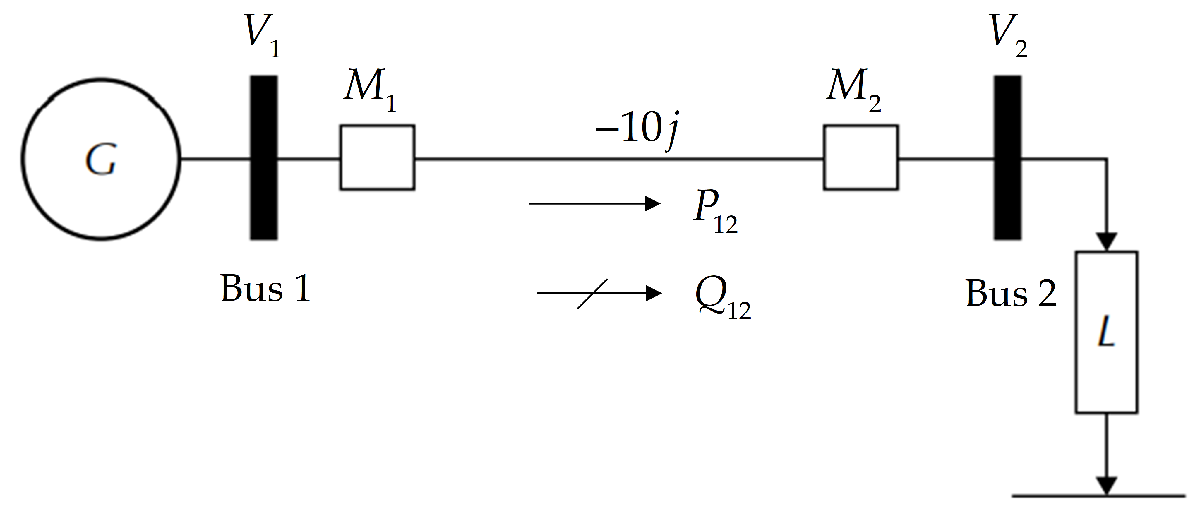

Figure 2. The two-bus system. 

**NOTE**: The network equations were obtained using equations (6) and (7) of the following section: 

Power flow through a "lossless" transmission line [2]. 

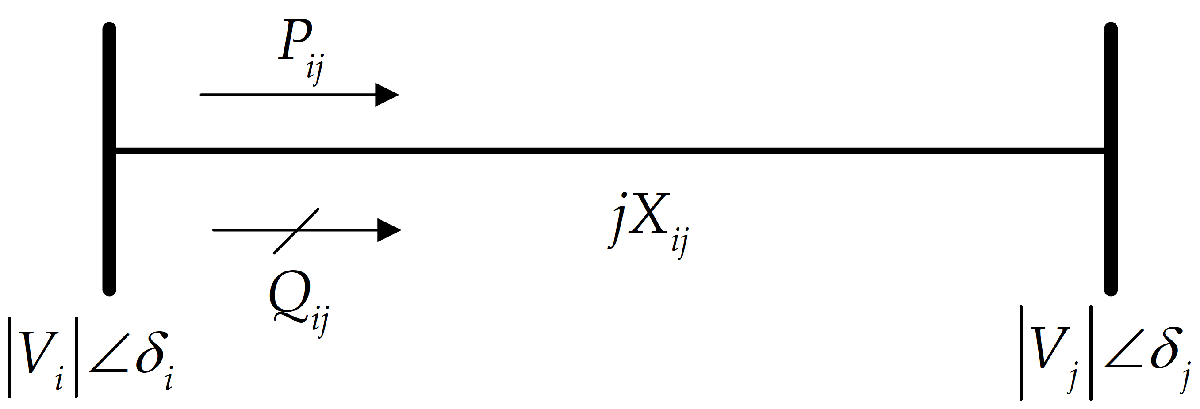


$$\bar{I_{\textrm{ij}} } =\frac{\bar{V_i } -\bar{V_j } }{{\textrm{jX}}_{\textrm{ij}} }\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$
            
$$\begin{array}{l}
S_{ij} =P_{ij} +Q_{ij} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)\\
S_{ij}^* =P_{ij} -Q_{ij} ={\bar{V} }_j^{*\;} \bar{I_{ij} } \;\;\;\;\;\;\;\left(3\right)
\end{array}$$
          
$$\begin{array}{l}
P_{ij} =\mathrm{Re}\left(S_{ij}^* \right)=\mathrm{Re}\left({\bar{V} }_j^{*\;} \bar{I_{ij} } \right)\;\;\;\;\;\left(4\right)\\
{\;Q}_{ij} =\mathrm{Im}\left(S_{ij}^* \right)\;=\mathrm{Im}\left({\bar{V} }_j^{*\;} \bar{I_{ij} } \right)\;\;\;\left(5\right)
\end{array}$$
          
$${\bar{V} }_j^{*\;} =\left|\bar{V_j } \right|\angle -\delta_j$$


If the transmission line is "lossless", the active power flow from node *i* to node *j* will be the same as active power flow from node *j *to node *i. *Therefore:


$$P_{ij} =P_{ji}$$
 

Substituting (1) in (4), the active power flow is 


$$\begin{array}{l}
P_{\textrm{ij}} =\textrm{Re}\left({\bar{V} }_j^{*\;} \bar{I_{\textrm{ij}} } \right)=\textrm{Re}\left({\bar{V} }_j^{*\;} \frac{\bar{V_i } -\bar{V_j } }{{\textrm{jX}}_{\textrm{ij}} }\right)=\textrm{Re}\left(\frac{{\bar{V} }_j^{*\;} \bar{V_i } }{{\textrm{jX}}_{\textrm{ij}} }-\frac{{\bar{V} }_j^{*\;} \bar{V_j } }{{\textrm{jX}}_{\textrm{ij}} }\right)\\
\;\;\;\;\;\;\;\;=\textrm{Re}\left(\frac{\left|\bar{V_i } \right|\left|\bar{V_j } \right|}{X_{\textrm{ij}} }\angle \left(-\delta_j +\delta_i -{90}^{\circ } \right)-\frac{{\left|\bar{V_j } \right|}^2 }{X_{\textrm{ij}} }\angle \left(-\delta_j +\delta_j -{90}^{\circ } \right)\right)\\
\;\;\;\;\;\;\;\;\;=\frac{\left|\bar{V_i } \right|\left|\bar{V_j } \right|}{X_{\textrm{ij}} }\sin \left(\delta_i -\delta_j \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(6\right)
\end{array}$$


Substituting (1) in (5), the reactive power flow is:


$$\begin{array}{l}
Q_{ij} =\mathrm{Im}\left({\bar{V} }_j^{*\;} \bar{I_{ij} } \right)=\mathrm{Im}\left(\frac{\left|\bar{V_i } \right|\left|\bar{V_j } \right|}{X_{ij} }\angle \left(-\delta_j +\delta_i -{90}^{\circ } \right)-\frac{{\left|\bar{V_j } \right|}^2 }{X_{ij} }\angle \left(-\delta_j +\delta_j -{90}^{\circ } \right)\right)\\
\;\;\;\;\;\;=\frac{{\left|\bar{V_i } \right|}^2 -\left|\bar{V_i } \right|\left|\bar{V_j } \right|\mathrm{cos}\left(\delta_i -\delta_j \right)}{X_{ij} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\right)\;
\end{array}$$


***Procedure: ***

- Define initial state variables:  

x0 = [0;1.02;1.0]

x0 =          0
    1.0200
    1.0000


           2. Define the state variables,  $\mathbf{x}=\left\lbrack \begin{array}{ccc}
\delta_2  & V_1  & V_2 
\end{array}\right\rbrack$. 

syms d2 V1 V2   % Creating a simbolic variables
x = [d2; V1; V2]

$$x = \left(\begin{array}{c} d_{2}\\ V_{1}\\ V_{2} \end{array}\right)$$

         3. Creare the vector of mesurements ($\mathit{\mathbf{Z}}$) and  the vector of initial network equations (${\mathbf{F}}_0 \left(\mathbf{x}\right)$)

Z = [1.02; 1.0; 2.0; 0.2]

Z =     1.0200
    1.0000
    2.0000
    0.2000


Fx =[x(2);x(3); -10*x(2)*x(3)*sin(x(1));10*x(2)^2-10*x(2)*x(3)*cos(x(1))]

$$Fx = \left(\begin{array}{c} V_{1}\\ V_{2}\\ -10\,V_{1}\,V_{2}\,\sin\left(d_{2}\right)\\ 10\,{V_{1}}^{2}-10\,V_{1}\,V_{2}\,\cos\left(d_{2}\right) \end{array}\right)$$

         4. Create the covarince matrix ($\mathbf{R}$):   

r=[0.05^2;0.05^2;0.1^2;0.1^2];
R = diag(r)

R =     0.0025         0         0         0
         0    0.0025         0         0
         0         0    0.0100         0
         0         0         0    0.0100


         5. Compute  the jacobian matrix  ${\mathbf{H}} \left(\mathbf{x}\right)$: 

m = 4; % number of network equations 
n = 3; % number of state variables

for i = 1:m
    for j = 1:n
        H(i,j)=diff(Fx(i),x(j));
    end
end
H   

$$H = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -10\,V_{1}\,V_{2}\,\cos\left(d_{2}\right) & -10\,V_{2}\,\sin\left(d_{2}\right) & -10\,V_{1}\,\sin\left(d_{2}\right)\\ 10\,V_{1}\,V_{2}\,\sin\left(d_{2}\right) & 20\,V_{1}-10\,V_{2}\,\cos\left(d_{2}\right) & -10\,V_{1}\,\cos\left(d_{2}\right) \end{array}\right)$$

       6. Compute the state variables using equation (4). Firts define the number of iterations (K). 

K = 3;

for k=1:K
    if k==1
       xk = x0;
    else 
       xk = xnew; 
    end 
    
    Hk=subs(H,x,xk);
    Fxk=subs(Fx,x,xk);
           
    xnew = double( xk + inv(Hk'*inv(R)*Hk) * Hk'*inv(R) * (Z-Fxk))
end

xnew =    -0.1961
    1.0198
    1.0002


xnew =    -0.1972
    1.0105
    1.0097


xnew =    -0.1972
    1.0105
    1.0099


         7. Solve the network equations ($\mathbf{F}\left(\mathbf{x}\right)$) : 

Fx = subs(Fx,x,xnew); 
double(Fx)

ans =     1.0105
    1.0099
    1.9992
    0.2038
